# Cascaded ASC INDI Controller for Quadrotor with Drag Plate

This live script explains the theory and structure of the controller used to control a Bebop drone equipped with a drag plate on top to add non-negligile aerodynamic effects. 

The development of this controller follows from the conventional cascaded INDI controller with mainly two additions:

- actuator compensation in the inner loop

- state term compensation in the inner loop and in the outer loop

The controller should then be able to track better the generated trajectories and increase disturbance rejection. 

## 1. Quadrotor Model

The drone considered is a Bebop with a drag plate on top, as shown below

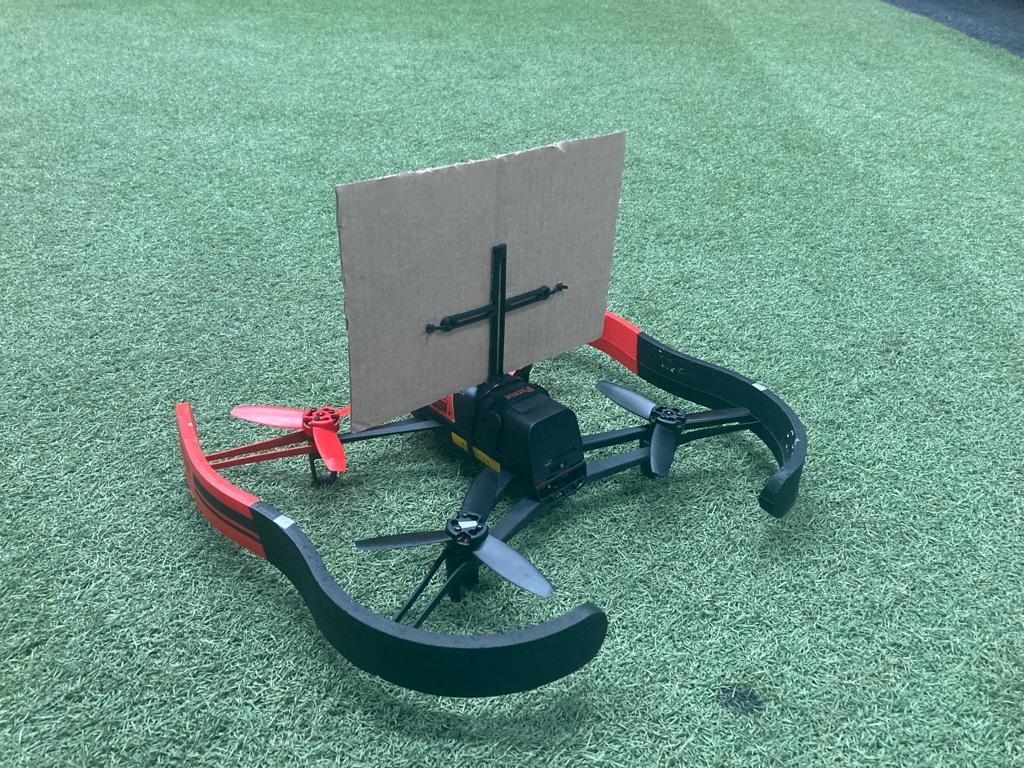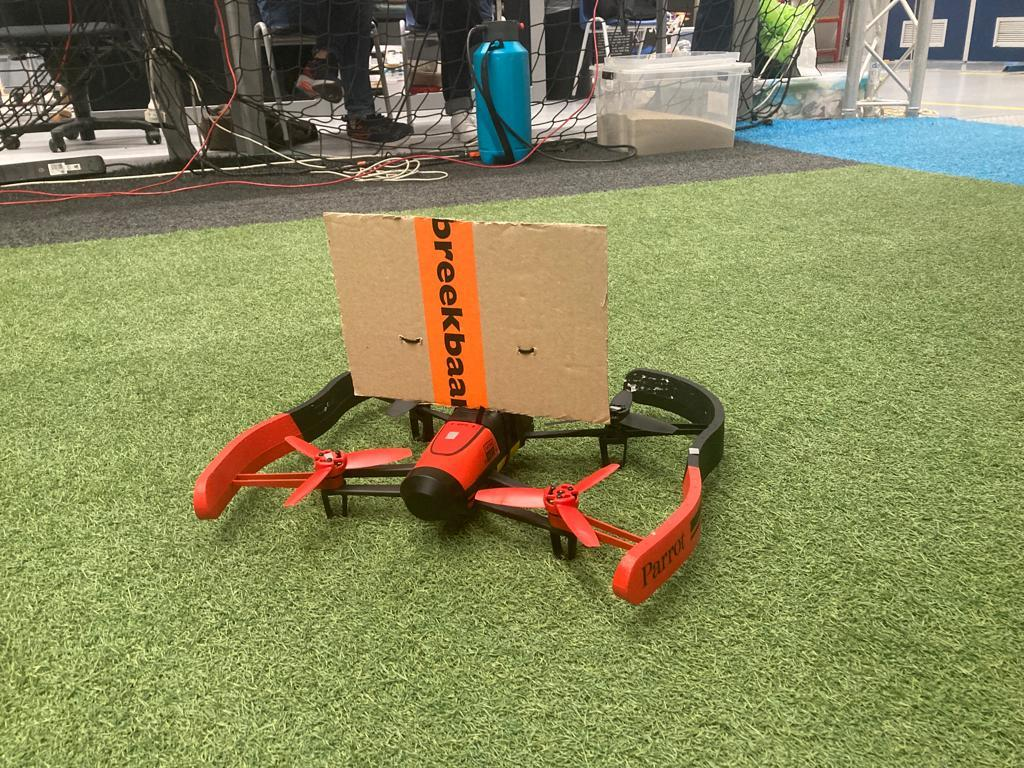

For the estimation of this model no drone aerodynamics are considered, except for the drag plate, and the angle of attack is zero. The quadrotor dynamics are expressed by longitudinal and rotational equation of motion such as


$$\left\lbrack \begin{array}{c}
\ddot{x_{\textrm{earth}} } \\
\ddot{y_{\textrm{earth}} } \\
\ddot{z_{\textrm{earth}} } 
\end{array}\right\rbrack =\frac{1}{m}\cdot \left(F_{a_{\textrm{earth}} } +F_{p_{\textrm{earth}} } \right)+\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack$$



$$\dot{\omega} =I^{-1} \cdot \left(-\omega \times I\cdot \omega +M_a +M_c +M_r \right)$$


Where the subscript $c$ stands for the moment and forces generated by the propellers, therefore the control inputs, and $r$ stands for the yaw moments induced by the rotors spinning.  

### 1.1. Transformation Matrices

To develop the tranformation matrices correctly, the considered world frame must be followed, together with the order of rotation. For this case we consider the earth frame as NED (North-East-Down) and the body frame as in the figure below. 

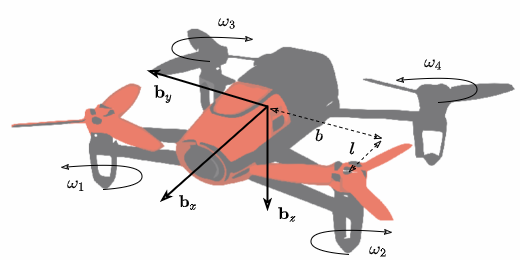

The attitude is described as the angles between the body frame axis and the earth axis. The single elements of rotations around each angle are therefore


$$\begin{array}{l}
R_{\phi } =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \phi  & -\sin \phi \\
0 & \sin \phi  & \cos \phi 
\end{array}\right\rbrack \\
R_{\theta } =\left\lbrack \begin{array}{ccc}
\cos \theta  & 0 & \sin \theta \\
0 & 1 & 0\\
-\sin \theta  & 0 & \cos \theta 
\end{array}\right\rbrack \\
R_{\psi } =\left\lbrack \begin{array}{ccc}
\cos \psi  & -\sin \psi  & 0\\
\sin \psi  & \cos \psi  & 0\\
0 & 0 & 1
\end{array}\right\rbrack 
\end{array}$$


These matrices will give the basis to build the rotation and transformation matrices needed. 

#### 1.1.1. Rotation Body to Ground

For the body to ground rotation and unconventional rotation order is ZXY, or 3-1-2, instead of ZYX, which is beneficial as it removes the influence of the yaw angle on the outer loop effectiveness matrix. The full matrix of rotation in the body frame therefore becomes


$$R_{\textrm{bg}} =R_{\theta } \cdot R_{\phi } \cdot R_{\psi }$$


#### 1.1.2. Euler Rates to Body Rates

For the euler rates and the body rates are not the same, they need to be converted body in the state estimation and in the reference model. For this we need rotation matrices as well. The goal is to relate an istantaneous change in Euler angles to the angular velocity. To build such matrix we start off backwards, from the last rotation, the pitch angle. The change from the identity vector for the pitch angle to the angular rate around the Y-axis, which is trivially an idenity matrix. 


$$q=\dot{\theta}$$


The second is the roll, which lags behind by a pitch rotation, therefore the pitch rotation matrix is required. For the heading, this lags behind two rotations, the pitch and roll rotation, in this order. This rotations must be then summed up to obtain the rotation matrix


$$R=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
\dot{\theta} \\
0
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
\cos \theta  & 0 & \sin \theta \\
0 & 1 & 0\\
-\sin \theta  & 0 & \cos \theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{\phi} \\
0\\
0
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
\cos \theta  & 0 & \sin \theta \\
0 & 1 & 0\\
-\sin \theta  & 0 & \cos \theta 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \phi  & -\sin \phi \\
0 & \sin \phi  & \cos \phi 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
0\\
\dot{\psi} 
\end{array}\right\rbrack$$


which leads to the matrix


$$R=\left\lbrack \begin{array}{ccc}
0 & \cos \theta  & \cos \phi \sin \theta \\
1 & 0 & -\sin \phi \\
0 & -\sin \theta  & \cos \phi \cos \theta 
\end{array}\right\rbrack$$


Through symbolic calculation we obtain the inverse, to perform the inverse operation. 

[(sin(Phi)*sin(Theta))/cos(Phi) 1 (cos(Theta)*sin(Phi))/cos(Phi);
cos(Theta) 0 -sin(Theta);
sin(Theta)/cos(Phi) 0 cos(Theta)/cos(Phi);]

Unrecognized function or variable 'Phi'.

#### 1.1.3. Aerodynamic Frame

The transformation from the aerodynamic frame to the body frame


$$R_{\textrm{wb}} =\left\lbrack \begin{array}{ccc}
\cos \left(\alpha \right)\cos \left(\beta \right) & -\cos \left(\alpha \right)\sin \left(\beta \right) & -\sin \left(\alpha \right)\\
\sin \left(\beta \right) & \cos \left(\beta \right) & 0\\
\sin \left(\alpha \right)\cos \left(\beta \right) & -\sin \left(\alpha \right)\sin \left(\beta \right) & \cos \left(\alpha \right)
\end{array}\right\rbrack$$


### 1.2. Forces and Moments due to propeller action

The control input driven forces can be modeled as follows. Since the propellers are fixed in the body frame, the vector for the thrust in the body frame is only non-zero in the z-direction. We use the rotation matrix for the earth frame to get the $F_{p_{\textrm{earth}} }$ term as


$$F_{p_{\textrm{earth}} } =R_{\textrm{bg}} \cdot \left\lbrack \begin{array}{c}
0\\
0\\
T
\end{array}\right\rbrack =R_{\textrm{bg}} \cdot \sum_4 \left\lbrack \begin{array}{c}
0\\
0\\
-K_t \cdot \Omega_i^2 
\end{array}\right\rbrack$$


Where $T$ is the collective thrust in the body frame, which can be expressed by the sum of the single thrusts of each motor in terms of their rotational speed. 

Based on the convention above, the rotational moments due to propeller action can be identified as follows. 


$$M_c =\left\lbrack \begin{array}{cccc}
-l_x \cdot K_t  & l_x \cdot K_t  & -l_x \cdot K_t  & l_x \cdot K_t \\
l_y \cdot K_t  & l_y \cdot K_t  & {-l}_y \cdot K_t  & -l_y \cdot K_t \\
K_m  & K_m  & {-K}_m  & {-K}_m 
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack }^2$$


While for the yaw due to spinninig is 


$$M_r =\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} }  & I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} } 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
\dot{\Omega_1 } \\
\dot{\Omega_2 } \\
\dot{\Omega_3 } \\
\dot{\Omega_4 } 
\end{array}\right\rbrack$$


Which are in terms of the quadrotor geometry and the rotational speed of the motors. 

### 1.3. Forces and Moments due to aerodynamics of drag plate

When the drone is moving, the plate mouted on top is submerged in an airflow, which creates drag. For this model, we assume that the wind direction is parallel to the velocity in the earth frame, in other words, the angle of attack is equal to the pitch angle. The model then simplifies to the free body diagram below

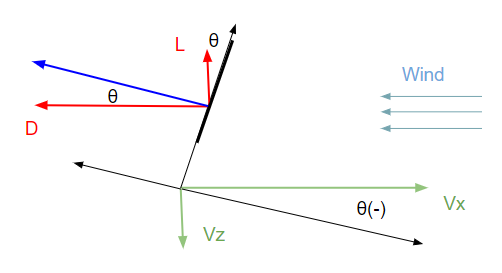

The plate, depending on the pitch of the drone, has different aerodynamic properties. Based on [Effects of aspect ratio and inclination angle on aerodynamic loads of a flat plate | Advances in Aerodynamics | Full Text (springeropen.com)](https://aia.springeropen.com/articles/10.1186/s42774-020-00038-7), the aerodynamic coefficients of a flat plate can be estimated. In this document, the plate is square and the aspect ratio AR is varied. For simplicity we assume an aspect ratio AR = 1, and proceed. 

For the coefficients, we have these plots

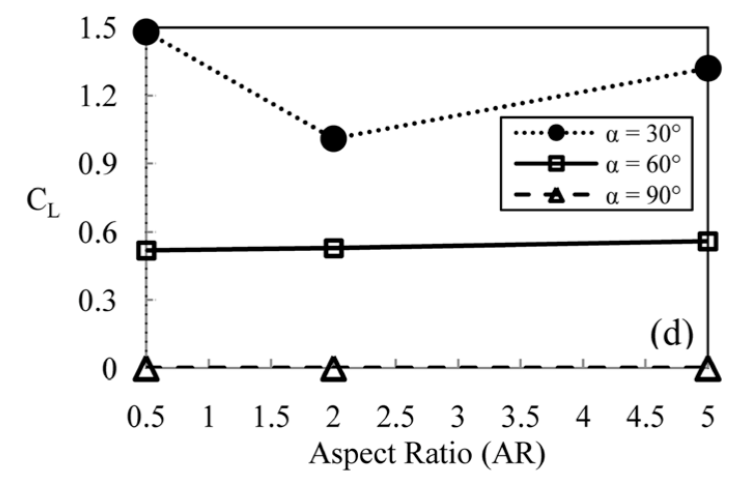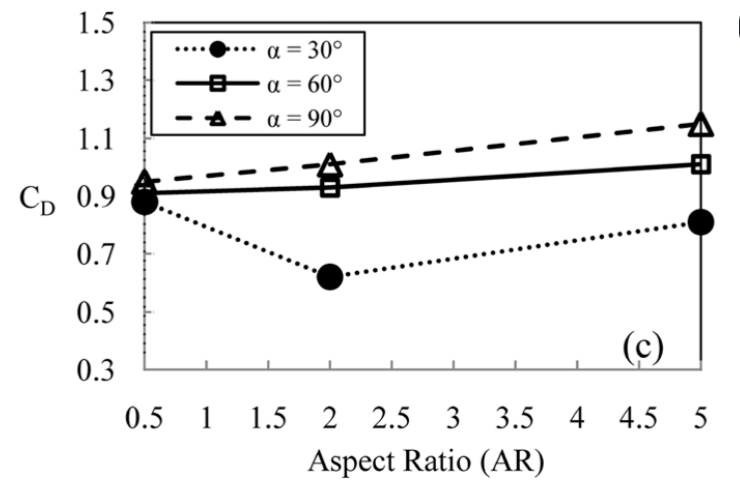

Where $\alpha$ indicates the angle of the plate with the flow. For $\alpha >90$, the drag behavior is assumed to be the same, while the lift behavior is inverted (logically, if the angle is inverted the air now pushes down, so negative lift). 

With a quick interpolation we obtain the following for $0<\alpha <90$

- Cl = **-0.0228***alpha + **2.01**

- Cd = **0.0033***alpha + **0.7**

visible from the linear fit

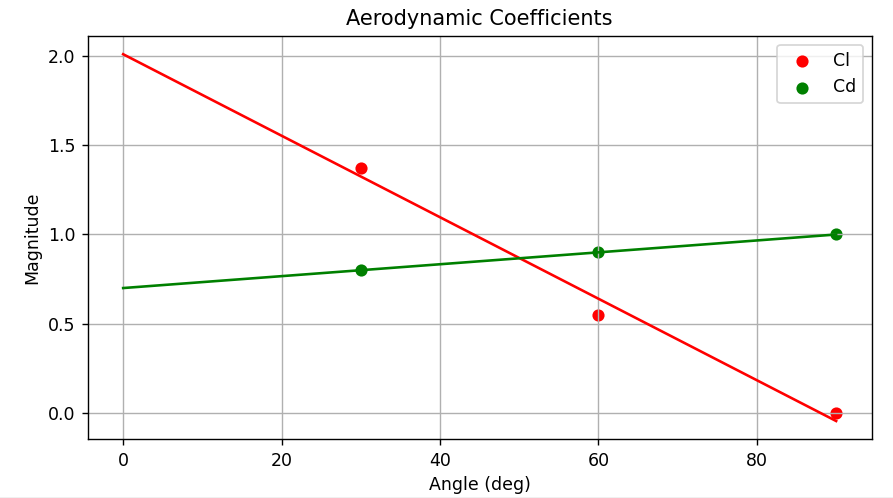

Given the information above, we can now derive the aerodynamic contribution of the drag plate, given the mentioned assumptions. Starting with the forces in the earth frame, we get


$${\left\lbrack \begin{array}{c}
{F_a }_x \\
F_{a_y } \\
F_{a_z } 
\end{array}\right\rbrack }_{\textrm{earth}} =R_{\textrm{bg}} \cdot {\left\lbrack \begin{array}{c}
{F_a }_x \\
F_{a_y } \\
F_{a_z } 
\end{array}\right\rbrack }_{\textrm{body}} =R_{\textrm{bg}} \cdot \left\lbrack \begin{array}{c}
-D\cdot \cos \left(\theta \right)+L\cdot \sin \left(\theta \right)\\
0\\
-D\cdot \sin \left(\theta \right)-L\cdot \cos \left(\theta \right)
\end{array}\right\rbrack$$


The lift and drag are simply estimated using the already shown coefficients and the velocity in the flow, which is the squared sum of the body velocities of the drone, omitting the lateral one


$$V=\sqrt{u^2 +w^2 }$$


Leading to


$$\begin{array}{l}
L=\frac{\rho \cdot S\cdot V^2 }{2}\cdot \left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\\
D=\frac{\rho \cdot S\cdot V^2 }{2}\cdot \left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+0\ldotp 7\right)
\end{array}$$


Note here that the absolute of the pitch angle is taken because the reverse is otherwise triggered twice for the lift force. 

The horizontal force in the body frame generates a pitching moment that we can model, while the other moments are neglected, leading to the moments 


$$M_a =\left\lbrack \begin{array}{c}
0\\
l_{\textrm{plate}\;} \cdot {{F_a }_x }_{\textrm{body}} \\
0
\end{array}\right\rbrack$$


Both equations can be fully expanded


$${\left\lbrack \begin{array}{c}
{F_a }_x \\
F_{a_y } \\
F_{a_z } 
\end{array}\right\rbrack }_{\textrm{earth}} =\left\lbrack \begin{array}{ccc}
c_{\theta } c_{\psi }  & -c_{\phi } s_{\psi } +s_{\phi } s_{\theta } c_{\psi }  & s_{\phi } s_{\psi } +c_{\phi } s_{\theta } c_{\psi } \\
c_{\theta } s_{\psi }  & c_{\phi } c_{\psi } +s_{\phi } s_{\theta } s_{\psi }  & -s_{\phi } c_{\psi } +c_{\phi } s_{\theta } s_{\psi } \\
-s_{\theta }  & s_{\phi } c_{\theta }  & c_{\phi } c_{\theta } 
\end{array}\right\rbrack \cdot \frac{\rho \cdot S\cdot \left(u^2 +w^2 \right)}{2}\cdot \left\lbrack \begin{array}{c}
-\left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)+0\ldotp 7\right)\cdot \frac{180}{\pi }\cdot \cos \left(\theta \right)+\left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\cdot \sin \left(\theta \right)\\
0\\
-\left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)+0\ldotp 7\right)\cdot \frac{180}{\pi }\cdot \sin \left(\theta \right)-\left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\cdot \cos \left(\theta \right)
\end{array}\right\rbrack$$



$$M_a =\left\lbrack \begin{array}{c}
0\\
l_{\textrm{plate}\;} \cdot \frac{\rho \cdot S\cdot \left(u^2 +w^2 \right)}{2}\cdot \left(-\left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+0\ldotp 7\right)\cdot \cos \left(\theta \right)+\left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\cdot \sin \left(\theta \right)\right)\\
0
\end{array}\right\rbrack$$


This form allows to better understand on what these variables depend on. 

## 2. Conventional Cascaded INDI

This section looks at the conventional cascaded controller, made of two loops. The concept is developed around the linearization of the control dependent part of the equations of motions and inversion. Which can be summarized in the equation below. 

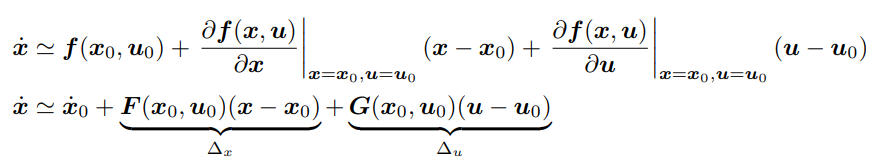

This is done for two separate loops. For each one a specific set of desired inputs and states is defined, and an inversion matrix is obtained. 

### 2.1. Inner Loop Design

For the inner loop we want to get the required RPM of each motor, therefore four inputs, by delivering four states to track, namely


$$x_{\textrm{inner}} =\left\lbrack \begin{array}{cccc}
\phi  & \theta  & \psi  & T
\end{array}\right\rbrack$$


with inputs


$$u_{\textrm{inner}} =\left\lbrack \begin{array}{cccc}
\Omega_1  & \Omega_2  & \Omega_3  & \Omega_4 
\end{array}\right\rbrack$$


As said, we look only at the control terms, not the state terms, which lead, for the first three states to the equation


$$\dot{\omega} =I^{-1} \cdot \left(M_p +M_r \right)=I^{-1} \cdot \left\lbrack \begin{array}{cccc}
-l_x \cdot K_t  & l_x \cdot K_t  & -l_x \cdot K_t  & l_x \cdot K_t \\
l_y \cdot K_t  & l_y \cdot K_t  & {-l}_y \cdot K_t  & -l_y \cdot K_t \\
K_m  & K_m  & {-K}_m  & {-K}_m 
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack }^2 +I^{-1} \cdot \left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} }  & I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} } 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
\dot{\Omega_1 } \\
\dot{\Omega_2 } \\
\dot{\Omega_3 } \\
\dot{\Omega_4 } 
\end{array}\right\rbrack$$


With the addition of the thrust component


$$T=\left\lbrack \begin{array}{cccc}
-{2\cdot K}_t \; & -{2\cdot K}_t \; & -{2\cdot K}_t \; & -{2\cdot K}_t \;
\end{array}\right\rbrack \cdot {\left\lbrack \begin{array}{c}
\Omega_1 \\
\Omega_2 \\
\Omega_3 \\
\Omega_4 
\end{array}\right\rbrack }^2$$


For better readibility, the rotation equation can be rewritten as


$$\dot{\omega} =\frac{1}{2}G_{1_{\omega } } \Omega^2 +T_s G_{2_{\omega } } \dot{\Omega}$$


With $G_{1_{\omega } }$ and $G_{2_{\omega } \;}$as 


$$\begin{array}{l}
G_{1_{\omega } } =2I_v^{\;-1} \left\lbrack \begin{array}{cccc}
-b\cdot K_t  & b\cdot K_t  & b\cdot K_t  & -b\cdot K_t \\
l\cdot K_t  & l\cdot K_t  & -l\cdot K_t  & -l\cdot K_t \\
K_m  & {-K}_m  & K_m  & {-K}_m 
\end{array}\right\rbrack \\
G_{2_{\omega } } =I_v^{\;-1} T_s^{-1} \left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} }  & I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} } 
\end{array}\right\rbrack 
\end{array}$$


The setup can be extended to the thrust, leading to


$$\left\lbrack \begin{array}{c}
\dot{\omega} \\
T
\end{array}\right\rbrack =\frac{1}{2}G_1 \Omega^2 +T_s G_2 \dot{\Omega}$$


with $G_1$ and $G_{2\;}$as


$$\begin{array}{l}
G_1 =2\cdot \left\lbrack \begin{array}{cccc}
\frac{-b\cdot K_t }{I_{\textrm{xx}} } & \frac{b\cdot K_t }{I_{\textrm{xx}} } & \frac{b\cdot K_t }{I_{\textrm{xx}} } & \frac{-b\cdot K_t }{I_{\textrm{xx}} }\\
\;\frac{l\cdot K_t }{I_{\textrm{yy}} } & \frac{l\cdot K_t }{I_{\textrm{yy}} } & \frac{-l\cdot K_t }{I_{\textrm{yy}} } & \frac{-l\cdot K_t }{I_{\textrm{yy}} }\\
\frac{K_m }{I_{\textrm{zz}} } & \frac{{-K}_m }{I_{\textrm{zz}} } & \frac{K_m }{I_{\textrm{zz}} } & \frac{{-K}_m }{I_{\textrm{zz}} }\\
-K_t  & -K_t  & -K_t  & -K_t 
\end{array}\right\rbrack \\
G_2 =I_v^{\;-1} T_s^{-1} \left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} }  & I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} } 
\end{array}\right\rbrack =I_v^{\;-1} T_s^{-1} \cdot \left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
I_{r_{\textrm{zz}} }  & {-I}_{r_{\textrm{zz}} }  & I_{r_{\textrm{zz}} }  & -I_{r_{\textrm{zz}} } \\
0 & 0 & 0 & 0
\end{array}\right\rbrack 
\end{array}$$


The linearization of the above leads to the INDI inversion law


$$\left\lbrack \begin{array}{c}
\dot{\omega} \\
T
\end{array}\right\rbrack ={\left\lbrack \begin{array}{c}
\dot{\omega} \\
T
\end{array}\right\rbrack }_0 +\frac{1}{2}\cdot G_1 \cdot 2\cdot \Omega \cdot \left(\Omega -\Omega_0 \right)+T_s G_2 \left(\dot{\Omega} -{\dot{\Omega} }_0 \right)$$


Which simplifies to


$$\left\lbrack \begin{array}{c}
\dot{\omega} \\
T
\end{array}\right\rbrack -{\left\lbrack \begin{array}{c}
\dot{\omega} \\
T
\end{array}\right\rbrack }_0 +G_2 \cdot z^{-1} \left(\Omega -\Omega_0 \right)=G_1 \cdot \Omega \cdot \left(\Omega -\Omega_0 \right)+G_2 \cdot \left(\Omega -\Omega_0 \right)$$


Which can be the inverted to get the incremental control command


$$\left(\Omega -\Omega_0 \right)={\left(G_1 \cdot \Omega +G_2 \right)}^+ \left(\left\lbrack \begin{array}{c}
\dot{\omega} -\dot{\omega_0 } \\
T-T_0 
\end{array}\right\rbrack +G_2 \cdot z^{-1} \left(\Omega -\Omega_0 \right)\right)$$


### 2.2. Outer Loop Design

The rotation and thrust command should be delivered from the outer loop and processed with a reference model. The outer loop law is obtained by looking at the longitudinal motion affected by the control inputs


$$\left\lbrack \begin{array}{c}
\ddot{x_{\textrm{earth}} } \\
\ddot{y_{\textrm{earth}} } \\
\ddot{z_{\textrm{earth}} } 
\end{array}\right\rbrack =\frac{1}{m}\cdot F_{p_{\textrm{earth}} } +\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack =\frac{1}{m}\cdot R_{\textrm{bg}} \cdot \sum_4 \left\lbrack \begin{array}{c}
0\\
0\\
-K_t \cdot \Omega_i^2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack =\frac{1}{m}\cdot \left\lbrack \begin{array}{ccc}
c_{\theta } c_{\psi }  & -c_{\phi } s_{\psi } +s_{\phi } s_{\theta } c_{\psi }  & s_{\phi } s_{\psi } +c_{\phi } s_{\theta } c_{\psi } \\
c_{\theta } s_{\psi }  & c_{\phi } c_{\psi } +s_{\phi } s_{\theta } s_{\psi }  & -s_{\phi } c_{\psi } +c_{\phi } s_{\theta } s_{\psi } \\
-s_{\theta }  & s_{\phi } c_{\theta }  & c_{\phi } c_{\theta } 
\end{array}\right\rbrack \cdot T+\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack$$


We see that the equation can be linearized for the control input that we need, which are


$$u_{\textrm{outer}} =\left\lbrack \begin{array}{ccc}
\phi  & \theta  & T
\end{array}\right\rbrack$$


given the states


$$x_{\mathrm{outer}} =\left\lbrack \begin{array}{ccc}
\dot{x_{\mathrm{earth}} }  & \dot{y_{\mathrm{earth}} }  & \dot{z_{\mathrm{earth}} } 
\end{array}\right\rbrack$$


The linearization here is obtained through a symbolic differentiation script, which leads to 

B_outer(1,1) = (T*(cos(Phi)*sin(Psi) - cos(Psi)*sin(Phi)*sin(Theta)))/m;
B_outer(1,2) = (T*cos(Phi)*cos(Psi)*cos(Theta))/m;
B_outer(1,3) = (sin(Phi)*sin(Psi) + cos(Phi)*cos(Psi)*sin(Theta))/m;

B_outer(2,1) = -(T*(cos(Phi)*cos(Psi) + sin(Phi)*sin(Psi)*sin(Theta)))/m;
B_outer(2,2) = (T*cos(Phi)*cos(Theta)*sin(Psi))/m;
B_outer(2,3) = -(cos(Psi)*sin(Phi) - cos(Phi)*sin(Psi)*sin(Theta))/m;

B_outer(3,1) = -(T*cos(Theta)*sin(Phi))/m;
B_outer(3,2) = -(T*cos(Phi)*sin(Theta))/m;
B_outer(3,3) = (cos(Phi)*cos(Theta))/m;

The outer loop is then concluded.

## 3. Reference Model and Error Controller (Inner Loop)

To get the feedforward we need to guess the dynamics of the rotational jerk. We have already the desired acceleration $\ddot{\eta_{\textrm{des}} } =\ddot{\eta_{\textrm{ref}} } +\ddot{\eta_{\textrm{ec}} }$, but we need the further differentiation of it, we need the jerk. Obtaining the jerk can be done by finding an ideal gain for the dynamics from acceleration to jerk, so


$$\eta_{\textrm{des}}^{\left(3\right)} =K_{\ddot{\eta} } \cdot \left(\ddot{\eta_{\textrm{cmd}} } -\ddot{\eta_{\textrm{ref}} } \right)$$


Ideally, this dynamics are as fast as the actuator, as the speed of the actuator affects directly the jerk, so it is safe to assume that $K_{\ddot{\eta} } \le K_{\textrm{act}}$. 

For the error controller, it is impossible to feed back the jerk, so that feedback is not there. However, the error controller will contain the tracking of the angular acceleration, leading to the expression


$$\eta_{\textrm{des}}^{\left(3\right)} =\eta_{\textrm{ref}}^{\left(3\right)} +\sum_{i=0} K_{{\textrm{ec}}_i } \cdot e_{\eta }^{\left(i\right)}$$


which would need an additional error coefficient for the error dynamics of the acceleration tracking. By looking at the expanded INDI control law proposed by Ewoud

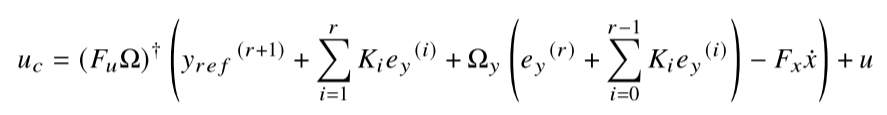

we can see that the error controller needs restructuring to obtain desired error dynamics. In brief, we need a new error controller so that


$$\begin{array}{l}
\eta_{\textrm{ec}}^{\left(3\right)} =\left({K_{\ddot{\textrm{ec}} } \cdot \left(\ddot{\eta_{\textrm{ref}} } -\ddot{\eta} \right)+K}_{\dot{\textrm{ec}} } \cdot \left(\dot{\eta_{\textrm{ref}} } -\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(\eta_{\textrm{ref}} -\eta \right)\right)+K_{\textrm{act}} \cdot \left(\left(\ddot{\eta_{\textrm{ref}} } -\ddot{\eta} \right)+K_{\dot{\textrm{ec}} } \cdot \left(\dot{\eta_{\textrm{ref}} } -\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(\eta_{\textrm{ref}} -\eta \right)\right)\\
\eta_{\textrm{ec}}^{\left(3\right)} ={\left(K_{\ddot{\textrm{ec}} } +K_{\textrm{act}} \right)\cdot \left(\ddot{\eta_{\textrm{ref}} } -\ddot{\eta} \right)+\;K}_{\dot{\textrm{ec}} } \cdot \left(1+K_{\textrm{act}} \right)\cdot \left(\dot{\eta_{\textrm{ref}} } -\dot{\eta} \right)+K_{\textrm{ec}} \cdot \left(1+K_{\textrm{act}} \right)\cdot \left(\eta_{\textrm{ref}} -\eta \right)
\end{array}$$


In addition to that, also the thrust increment must be adapted and multiplied by the dynamics


$$\dot{T_{\textrm{cmd}} } =K_{\textrm{act}} \cdot \left(T_{\textrm{cmd}} -T\right)$$


## 4. Actuator Compensation in the Inner Loop

The conventional INDI linearizes the dynamics above through fouries series transform. To include actuator dynamics of the type


$$\dot{\Omega} =K_{\textrm{act}} \left(\Omega_{\textrm{cmd}} -\Omega \right)\;$$


we need to differentiate further and extract the rotational speed. This differentiation does not include the state dynamics, as they are neglected anyway. The derivation with respect to time will therefore look like this


$$\left\lbrack \begin{array}{c}
\ddot{\omega} \\
\dot{T} 
\end{array}\right\rbrack =\frac{1}{2}G_1 2\Omega \dot{\Omega} +T_s G_2 \ddot{\Omega} =G_1 \Omega K_{\textrm{act}} \left(\Omega_{\textrm{cmd}} -\Omega \right)+T_s G_2 \ddot{\Omega}$$


The jerk feedforward is now generated by the reference model and used to extract the command increment, but first we need to solve for $\ddot{\Omega}$. In discrete time we have 


$$\ddot{\Omega} =\left(\dot{\Omega} -\dot{\Omega} z^{\;-1} \right)T_s^{-1} =$$

$$\left(K_{\textrm{act}} \left(\Omega_{\textrm{cmd}} -\Omega \right)-K_{\textrm{act}} \left(\Omega_{\textrm{cmd}} -\Omega \right)z^{\;-1} \right)T_s^{-1} =\left(\left(\Omega_{\textrm{cmd}} -\Omega \right)-\left(\Omega_{\textrm{cmd}} -\Omega \right)z^{\;-1} \right){K_{\textrm{act}} T}_s^{-1}$$


which added to the function leads to


$$\left\lbrack \begin{array}{c}
\ddot{\omega} \\
\dot{T} 
\end{array}\right\rbrack =\frac{1}{2}G_1 2\Omega \dot{\Omega} +T_s G_2 \ddot{\Omega} =G_1 K_{\textrm{act}} \Omega \left(\Omega_{\textrm{cmd}} -\Omega \right)+G_2 K_{\textrm{act}} \left(\left(\Omega_{\textrm{cmd}} -\Omega \right)-\left(\Omega_{\textrm{cmd}} -\Omega \right)z^{\;-1} \right)$$


and collecting the terms of increment results in


$$\left\lbrack \begin{array}{c}
\ddot{\omega} \\
\dot{T} 
\end{array}\right\rbrack =K_{\textrm{act}} \left(G_1 \Omega +G_2 \right)\left(\Omega_{\textrm{cmd}} -\Omega \right)-G_2 K_{\textrm{act}} \left(\Omega_{\textrm{cmd}} -\Omega \right)z^{\;-1}$$


Now we can perform an inversion, which will look like


$$\Omega_{\textrm{cmd}} -\Omega ={\left(K_{\textrm{act}} \left(G_1 \Omega +G_2 \right)\right)}^+ \left(\left\lbrack \begin{array}{c}
\ddot{\omega} \\
\dot{T} 
\end{array}\right\rbrack +G_2 K_{\textrm{act}} \left(\Omega_{\textrm{cmd}} -\Omega \right)z^{\;-1} \right)$$


So now its clear where we have to compensate for actuator dynamics. The pseudoinverse must be made on the multiplication between the two matrices and the same goes for the feedback of the G2 term. We can see here that the derivative of the thrust is required for the inversion. This one can be simply obtained by 


$$\dot{T} =K_{\textrm{act}} \cdot \left(T-T_0 \right)$$


Which is done by multiplying the thrust increment for the actuator dynamics. 

## 5. Actuator Compensation for Outer Loop

The outer loop of the controller has still the conventional INDI method. This can be extended to the new INDI method, so that we have both actuator compensation and state term compensation. To begin with, we have


$$\left\lbrack \begin{array}{c}
\ddot{x_{\textrm{earth}} } \\
\ddot{y_{\textrm{earth}} } \\
\ddot{z_{\textrm{earth}} } 
\end{array}\right\rbrack =\frac{1}{m}\cdot \left\lbrack \begin{array}{ccc}
c_{\theta } c_{\psi }  & -c_{\phi } s_{\psi } +s_{\phi } s_{\theta } c_{\psi }  & s_{\phi } s_{\psi } +c_{\phi } s_{\theta } c_{\psi } \\
c_{\theta } s_{\psi }  & c_{\phi } c_{\psi } +s_{\phi } s_{\theta } s_{\psi }  & -s_{\phi } c_{\psi } +c_{\phi } s_{\theta } s_{\psi } \\
-s_{\theta }  & s_{\phi } c_{\theta }  & c_{\phi } c_{\theta } 
\end{array}\right\rbrack \cdot T+\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack$$


with the input vetor being


$$u_{\textrm{outer}} =\left\lbrack \begin{array}{ccc}
\phi  & \theta  & T
\end{array}\right\rbrack$$


Now, we actually have the actuator dynamics of out inputs, which can be expressed as


$$\begin{array}{l}
\dot{\phi} =K_{\phi } \cdot \left(\phi -\phi_0 \right)\\
\dot{\theta} =K_{\theta } \cdot \left(\theta -\theta_0 \right)\\
\dot{T} =K_{\textrm{act}} \cdot \left(T-T_0 \right)
\end{array}$$


The gains we use for the dynamics of the output are then taken from the inner loop reference model for the angles and the motor dynamics for the thrust. If we consider the extended inversion law

we see that we should obtain the partials of 


$$F_{\textrm{outer}} =\frac{1}{m}\cdot \left\lbrack \begin{array}{ccc}
c_{\theta } c_{\psi }  & -c_{\phi } s_{\psi } +s_{\phi } s_{\theta } c_{\psi }  & s_{\phi } s_{\psi } +c_{\phi } s_{\theta } c_{\psi } \\
c_{\theta } s_{\psi }  & c_{\phi } c_{\psi } +s_{\phi } s_{\theta } s_{\psi }  & -s_{\phi } c_{\psi } +c_{\phi } s_{\theta } s_{\psi } \\
-s_{\theta }  & s_{\phi } c_{\theta }  & c_{\phi } c_{\theta } 
\end{array}\right\rbrack \cdot T+\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack$$


and then add the actuator dynamics, resulting in


$$\left\lbrack \begin{array}{c}
x_{\textrm{earth}}^{\left(3\right)} \\
y_{\textrm{earth}}^{\left(3\right)} \\
z_{\textrm{earth}}^{\left(3\right)} 
\end{array}\right\rbrack =\frac{{\partial F}_{\textrm{outer}} }{\partial u_{\textrm{outer}} }\cdot \left\lbrack \begin{array}{c}
K_{\phi } \cdot \left(\phi -\phi_0 \right)\\
K_{\theta } \cdot \left(\theta -\theta_0 \right)\\
K_{\textrm{act}} \cdot \left(T-T_0 \right)
\end{array}\right\rbrack =\frac{{\partial F}_{\textrm{outer}} }{\partial u_{\textrm{outer}} }\cdot \left\lbrack \begin{array}{ccc}
K_{\phi }  & 0 & 0\\
0 & K_{\theta }  & 0\\
0 & 0 & K_{\textrm{act}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\phi -\phi_0 \\
\theta -\theta_0 \\
T-T_0 
\end{array}\right\rbrack$$


Which has the same structure of the inner loop extension, but with different actuator dynamics. But in the error controller and the reference model we can specify only one gain! The solution is then to choose the slowest one, in this case the attitude dynamics. 

## 6. State Compensation for the Inner Loop (Higher Order)

The dynamics considered for the inner loop are affected by the moment of the drag plate. These can be compensated for by following the higher order INDI approach. We start by considering the rotational dynamics with also the drag plate moment


$$\dot{\omega} =I^{-1} \cdot \left(M_a +M_c +M_r \right)=I^{-1} \cdot \left(M_a \right)+I^{-1} \cdot \left(M_c +M_r \right)$$


If we expand this we see


$$\dot{\omega} =I^{-1} \cdot \left\lbrack \begin{array}{c}
0\\
l_{\textrm{plate}\;} \cdot \frac{\rho \cdot S\cdot \left(u^2 +w^2 \right)}{2}\cdot \left(-\left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+0\ldotp 7\right)\cdot \cos \left(\theta \right)+\left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\cdot \sin \left(\theta \right)\right)\\
0
\end{array}\right\rbrack +\frac{1}{2}G_1 \Omega^2 +T_s G_2 \dot{\Omega}$$


Now, if we differentiate further we get to the form that allows to invert. Now this form will contain both the state term and the control term, for the pitch at least. For simplicity, we call the control part $\ddot{\omega_{\textrm{control}} }$, which gives us


$$\dot{\omega} =\ddot{\omega_{\textrm{state}} } +\ddot{\omega_{\textrm{control}} }$$


What is then the term $\ddot{\omega_{\textrm{state}} }$? To answer this question, we need to look at the general formulation for the higher order reference model from the literature

This means that the state term needs to be derived by the state, which is


$$x_{\textrm{inner}} =\left\lbrack \begin{array}{cccccc}
\dot{x}  & \dot{y}  & \dot{z}  & \phi  & \theta  & \psi 
\end{array}\right\rbrack$$


This means that we need to derive for each of the state and multiply for its derivative. Assuming that Cd and Cl are constant, we can express the state term as


$$F_{S_{\theta } } =Q\cdot \left(u^2 +w^2 \right)\cdot \left(-C_D \cdot \cos \left(\theta \right)+C_L \cdot \sin \left(\theta \right)\right)$$


with


$$Q=\frac{l_{\textrm{plate}} }{I_{\textrm{yy}} }\cdot \frac{\rho \cdot S}{2}$$


Now we need to express the velocity in term of the states. This is the body velocity, which means that we can express it as


$$\left\lbrack \begin{array}{c}
u\\
v\\
w
\end{array}\right\rbrack =R_{\textrm{bg}}^T \cdot \left\lbrack \begin{array}{c}
\dot{x} \\
\dot{y} \\
\dot{z} 
\end{array}\right\rbrack$$


Which makes the expression in terms of the states only. The expression can be then derived for all the states and multiplied for its derivatives to deliver then the state compensation term. The compensation is then perfectly sent. 

## 7. State Compensation for the Outer Loop (Higher Order)

The drag plate induces also longitudinal accelerations. These should be compensated where we control the longitudinal acceleration, meaning in the outer loop. Now, we look at the dynamics of the longitudinal motion, which is 


$$\left\lbrack \begin{array}{c}
\ddot{x_{\textrm{earth}} } \\
\ddot{y_{\textrm{earth}} } \\
\ddot{z_{\textrm{earth}} } 
\end{array}\right\rbrack =\frac{1}{m}\cdot \left(\left\lbrack \begin{array}{ccc}
c_{\theta } c_{\psi }  & -c_{\phi } s_{\psi } +s_{\phi } s_{\theta } c_{\psi }  & s_{\phi } s_{\psi } +c_{\phi } s_{\theta } c_{\psi } \\
c_{\theta } s_{\psi }  & c_{\phi } c_{\psi } +s_{\phi } s_{\theta } s_{\psi }  & -s_{\phi } c_{\psi } +c_{\phi } s_{\theta } s_{\psi } \\
-s_{\theta }  & s_{\phi } c_{\theta }  & c_{\phi } c_{\theta } 
\end{array}\right\rbrack \cdot \frac{\rho \cdot S\cdot \left(u^2 +w^2 \right)}{2}\cdot \left\lbrack \begin{array}{c}
-\left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)+0\ldotp 7\right)\cdot \frac{180}{\pi }\cdot \cos \left(\theta \right)+\left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\cdot \sin \left(\theta \right)\\
0\\
-\left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)+0\ldotp 7\right)\cdot \frac{180}{\pi }\cdot \sin \left(\theta \right)-\left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\cdot \cos \left(\theta \right)
\end{array}\right\rbrack +F_{p_{\textrm{earth}} } \right)+\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack$$


We can take the state term only and call it $F_{S_{\textrm{outer}} }$, which contains both the compensator for the x acceleration and the z acceleration. We follow the same procedure as for the inner loop, since now the outer loop is also of the higher order type. 

Where the states are


$$X_{\textrm{outer}} =\left\lbrack \begin{array}{cccc}
\dot{x}  & \dot{y}  & \dot{z}  & \psi 
\end{array}\right\rbrack$$


Note that both $\theta$ and $\phi$ are treated as input signals here. So we need to derive the function by the states and multiply them for the increment. We set the term as follows then


$$F_{S_{\textrm{outer}} } =P\cdot \left(u^2 +w^2 \right)\cdot R_{\textrm{bg}} \cdot \left\lbrack \begin{array}{c}
F_{x_{\textrm{body}} } \\
0\\
F_{z_{\textrm{body}} } 
\end{array}\right\rbrack =P\cdot \left(u^2 +w^2 \right)\cdot R_{\textrm{bg}} \cdot \left\lbrack \begin{array}{c}
-\left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)+0\ldotp 7\right)\cdot \frac{180}{\pi }\cdot \cos \left(\theta \right)+\left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\cdot \sin \left(\theta \right)\\
0\\
-\left(0\ldotp 0033\cdot \left(\frac{\pi }{2}+\theta \right)+0\ldotp 7\right)\cdot \frac{180}{\pi }\cdot \sin \left(\theta \right)-\left(-0\ldotp 0228\cdot \left(\frac{\pi }{2}+\theta \right)\cdot \frac{180}{\pi }+2\ldotp 01\right)\cdot \cos \left(\theta \right)
\end{array}\right\rbrack$$


with


$$P=\frac{\rho \cdot S}{m\cdot 2}$$


The compensation term would then result in


$${\left\lbrack \begin{array}{c}
x^{\left(3\right)} \\
y^{\left(3\right)} \\
z^{\left(3\right)} \\
\ddot{\psi} 
\end{array}\right\rbrack }_{\Delta x} =\frac{{\partial F}_{S_{{\textrm{outer}}_x } } }{\partial X_{\textrm{outer}} }\cdot \left\lbrack \begin{array}{c}
\ddot{x} \\
\ddot{y} \\
\ddot{z} \\
\dot{\psi} 
\end{array}\right\rbrack$$


This means that the terms should be subtracted from the jerk feedforward. 

NOTE: issues with the heading, tbd. 

## 8. Delays and Complementary Filter

Even if the state compensation works fine for undelayed signals, the filters applied to reduce noise add a significant delay to the compensator signal, which is still beneficial, but is not perfect, which is suboptimal. In order to fix this delay issue, an idea could be the use of a complementary filter as in the diagram below. 

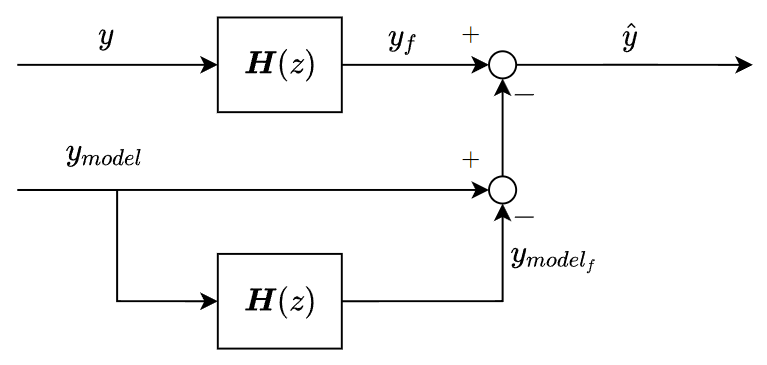

The state would require the use of a model to estimate the expected value of the interested variable and then compensate for the delay already. 

### 8.1 Building the complementary filter

In general, the state values that we need to filter are the noisy ones, in other words, the accelerations, both longitudinal and rotational. Let's start with the rotational ones. The data obtained from the drone is measured by the gyro, which measures the angular body velocity. The acceleration signal requires a discrete time derivative. This obtained signal is filtered. 

So, we have a "clean" $\omega$, we can integrate it and so on, and we can use it to model the angular acceleration to send it to the complementary filter. 

#### 8.1.1 Filter for angular acceleration

The angular acceleration is 


$$\dot{\omega} =I^{-1} \cdot \left(-\omega \times I\cdot \omega +M_a +M_c +M_r \right)$$


Which depends on the angular acceleration and the RPM, plus the state term. Lets try to not consider the state term for the time being. 